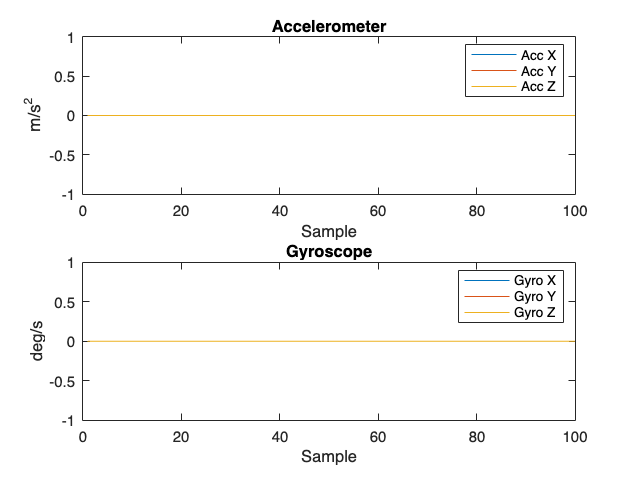

% Open the serial port
port = serialport("/dev/tty.usbmodem135745001", 115200);  % Replace COM5 with your Teensy port

% Configure end of line
configureTerminator(port, "LF");  % Teensy sends \n at the end

% Flush buffer
flush(port);

% Set how many samples you want to read
numSamples = 100;

% Preallocate for performance
data = zeros(numSamples, 6);

for i = 1:numSamples
    % Read line from serial
    line = readline(port);  

    % Look for the prefix
    if startsWith(line, "IMU:")
        % Remove prefix and split the rest
        raw = extractAfter(line, "IMU:");
        values = sscanf(raw, "%f,%f,%f,%f,%f,%f");

        if numel(values) == 6
            data(i, :) = values';
        end
    end
end

% Close the serial port
clear port;

% Plot accelerometer and gyro
t = 1:numSamples;
figure;
subplot(2,1,1);
plot(t, data(:,1:3)); legend('Acc X','Acc Y','Acc Z');
title('Accelerometer'); xlabel('Sample'); ylabel('m/s^2');

subplot(2,1,2);
plot(t, data(:,4:6)); legend('Gyro X','Gyro Y','Gyro Z');
title('Gyroscope'); xlabel('Sample'); ylabel('deg/s');